## 插值法

1.分段插值、插值多项式、三角插值（需用到傅里叶变换等复杂的数学工具）

2.龙格现象：高次插值，在两端处波动极大，产生明显的震荡，在不熟悉曲线运动的趋势的前提下，不要轻易使用高次插值

3.分段低次插值

4.埃尔米特插值：可保持节点和其对应的导数值也相同，甚至高阶倒数也相同

5.插值预测可能比灰色预测准确

6.适合用与样本点较少的情况

### 拉格朗日插值法

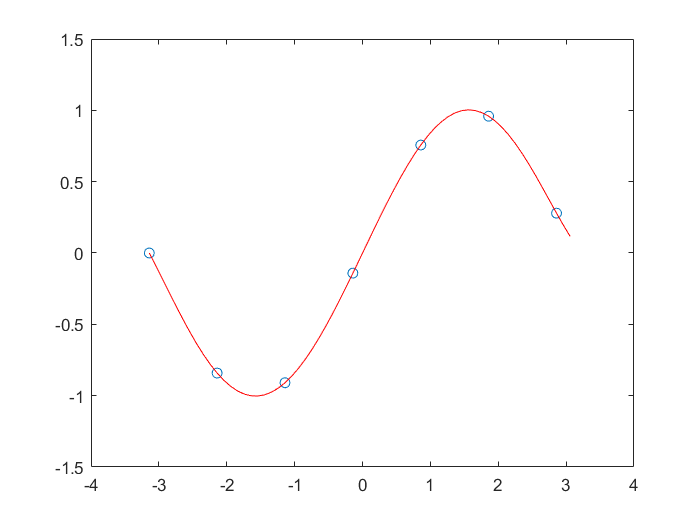

% 边缘会出现龙格现象，不常用
x = -pi : pi;
y = sin(x);
x_new = -pi : 0.1 : pi;

p = lagrange(x, y, x_new);

figure(1);
plot(x, y, 'o', x_new, p, 'r-')

### 分段三次埃尔米特插值（值相似，导数不要求）

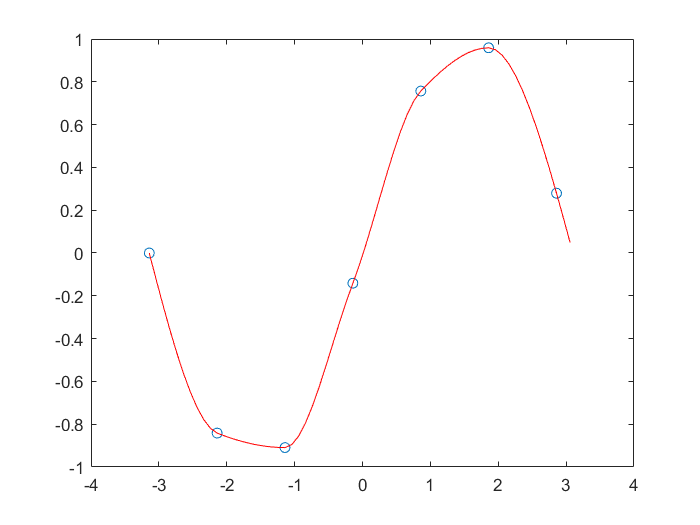

x = -pi : pi;
y = sin(x);
x_new = -pi : 0.1 : pi;


p = pchip(x, y, x_new);  % x,y--已知样本点的坐标， x_new--要插入点的横坐标

figure(1);
plot(x, y, 'o', x_new, p, 'r-')

### 三次样条插值和分段三次埃尔特插值的对比

三次样条插值（值相似，）

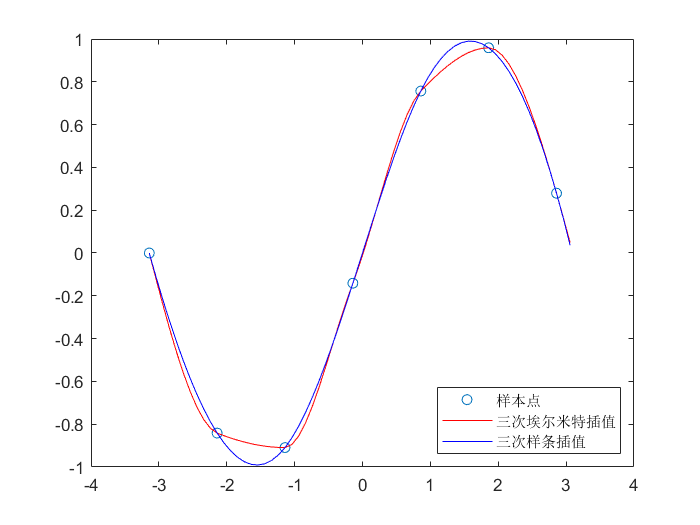

x = -pi : pi; 
y = sin(x); 
x_new = -pi : 0.1 : pi;


p1 = pchip(x, y, x_new);  % 分段三次埃尔米特插值
p2 = spline(x, y, x_new);  % 三次样条插值


figure(2);
plot(x, y, 'o', x_new, p1, 'r-', x_new, p2, 'b-')
legend('样本点', '三次埃尔米特插值', '三次样条插值', 'Location', 'SouthEast')   % 标注显示在东南方向

### 二维插值

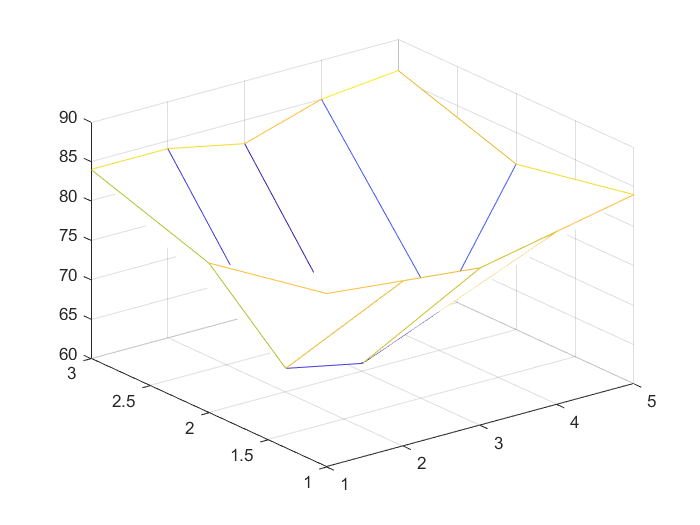

x = 1 : 5; 
y = 1 : 3;
z = [82 81 80 82 84;
     79 63 61 65 81;
     84 84 82 85 86];

x_new = 1 : 0.2 : 5;
x_new = x_new';
y_new = 1 : 0.2 : 3;

figure(3)
mesh(x, y, z);  % 生成曲线网格图

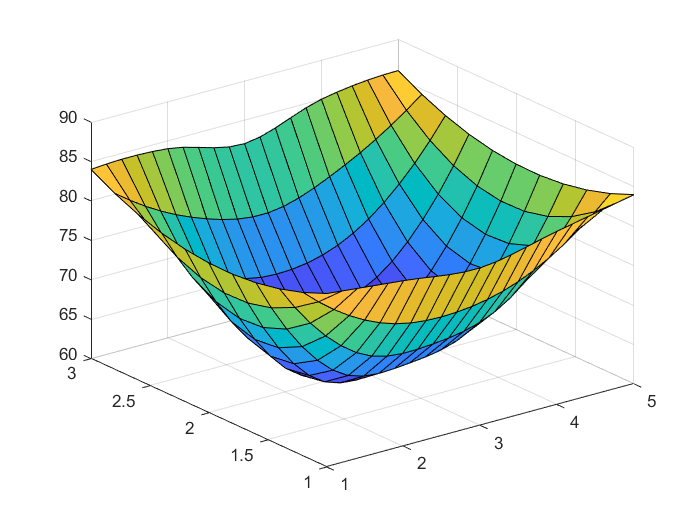



% 'nearest'--最邻近插值
% 'linear'--双线性插值
% 'spline'--双三次样条插值
% 'cubic'--双立方插值
% 缺省--双线性插值
z_new = interp2(x, y, z, x_new, y_new, 'cubic');
figure(4)
%mesh(x_new, y_new, z_new);  % 生成曲线网格图
surf(x_new, y_new, z_new);  % 生成曲面表面图

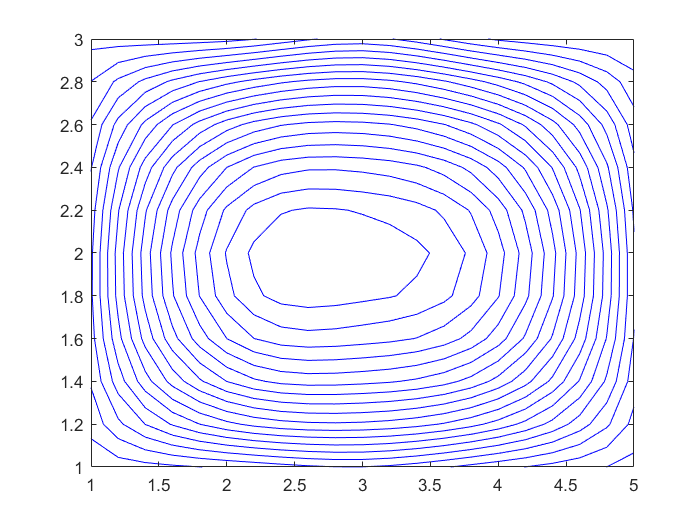


figure(5)
contour(x_new, y_new, z_new, 20, 'b');

### n 维插值

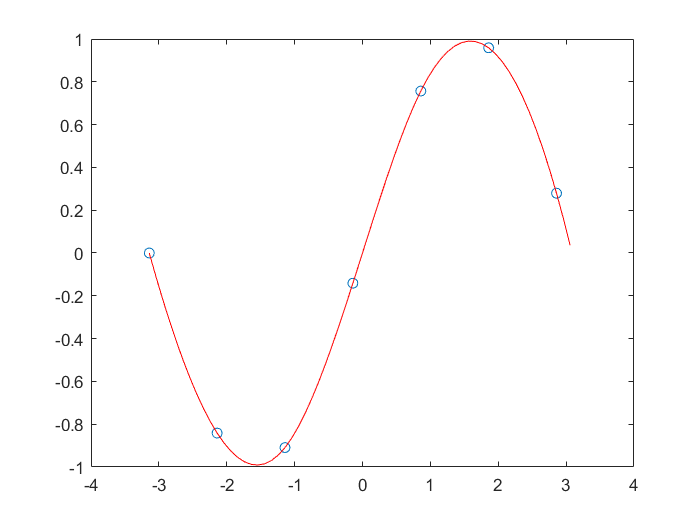

x = -pi : pi; 
y = sin(x); 
x_new = -pi : 0.1 : pi;

% 'nearest'--最邻近插值
% 'linear'--线性插值
% 'spline'--三次样条插值
% 'cubic'--立方插值
% 缺省--线性插值
p = interpn(x, y, x_new, 'spline');  % n 维插值函数


figure(6)
plot(x, y, 'o', x_new, p, 'r-')

### 散乱点插值

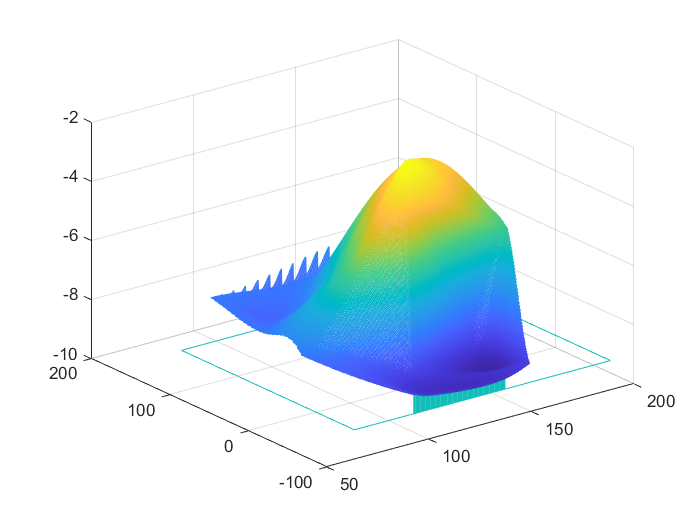

x = [129 140 103.5 88 185.5 195 105.5 157.5 107.5 77 81 162 162 117.5];
y = [7.5 141.5 23 147 22.5 137.5 85.5 -6.5 -81 3 56.6 -66.5 84 -33.5];
z = [-4 -8 -6 -8 -6 -8 -8 -9 -9 -8 -8 -9 -4 -9];

[xi, yi] = meshgrid(75 : 0.5 : 200, -70 : 0.5 : 150);
zi = griddata(x, y, z, xi, yi, 'cubic');

figure(7)
meshz(xi, yi, zi);

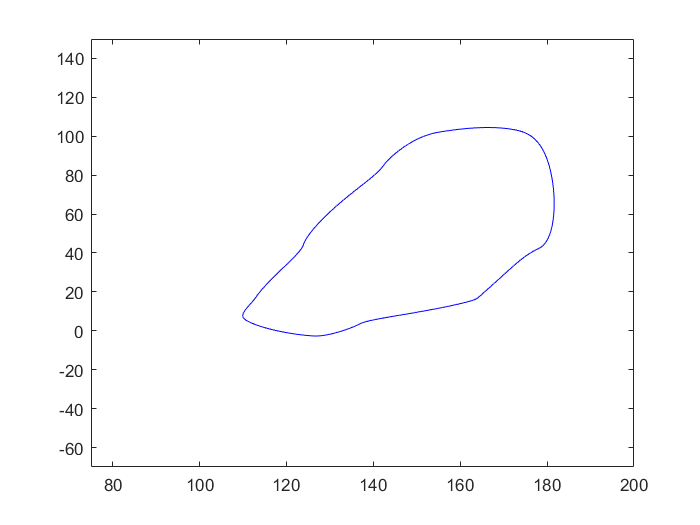


contour(xi, yi, zi, [-5 -5], 'b')